%% Estimate fundamentals from WDW data
clear;
wave = 400:5:650;

deutan = ieReadSpectra('wdwDeuteranopes.mat',wave);
%deutan = ieReadSpectra('wdwDeuteranopes.mat',wave);
protan = ieReadSpectra('wdwProtanopes.mat',wave);
load('wdwTritanopes','obsAverage');
tritan = interp1(obsAverage.wave,obsAverage.CMF,wave,'pchip','extrap');

protan  = ieScale(protan,1);
deutan = ieScale(deutan,1);
tritan  = ieScale(tritan,1);

stockman = ieReadSpectra('stockmanEnergy',wave);



## Compare L cone estimates

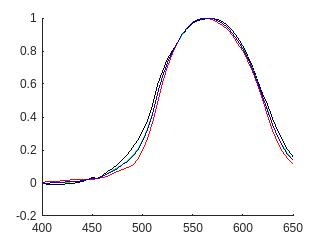

estimator1=estimatorIntersect(deutan,tritan);
estimator2=estimatorLowrank(deutan,tritan);
estimator3=estimatorNullNull(deutan,tritan);
figure; hold on
plot(wave,estimator1(:,1),'k')
plot(wave,estimator1(:,2),'r')
plot(wave,estimator2,'g')
plot(wave,estimator3,'b')

## Compare M cone estimates

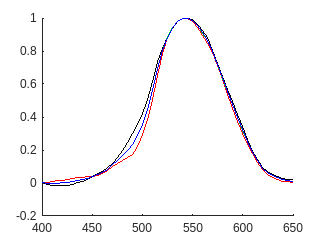

estimator1=estimatorIntersect(protan,tritan);
estimator2=estimatorLowrank(protan,tritan);
estimator3=estimatorNullNull(protan,tritan);
figure; hold on
plot(wave,estimator1(:,1),'k')
plot(wave,estimator1(:,2),'r')
plot(wave,estimator2,'g')
plot(wave,estimator3,'b')

## Compare S cone estimates

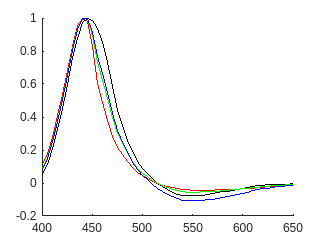

estimator1=estimatorIntersect(protan,deutan);
estimator2=estimatorLowrank(protan,deutan);
estimator3=estimatorNullNull(protan,deutan);
figure; hold on
plot(wave,estimator1(:,1),'k')
plot(wave,estimator1(:,2),'r')
plot(wave,estimator2,'g')
plot(wave,estimator3,'b')

## Do Lowrank and nulnullmethod always overlap? No!

IN many simulation esimatorLowrank and esimatorNUlNull seem to overlap. Is that true for the arbitrary case? No!

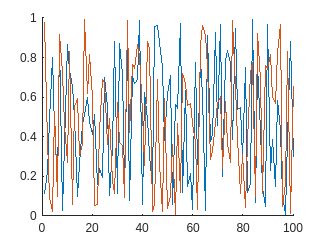

A=rand(100,2);
B=rand(100,2); 
figure;hold on
plot(A(:,2));plot(B(:,2))


figure;
estimator2=estimatorLowrank(A,B);
estimator3=estimatorNullNull(A,B);
norm(estimator3-estimator2)/norm(estimator2)

ans = 0.1383

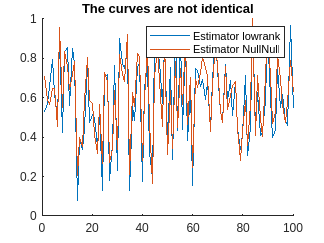


figure;hold on
title("The curves are not identical")
plot(estimator2)
plot(estimator3)
legend("Estimator lowrank","Estimator NullNull")

## However it seems like the nulnull method seems to converge to the lowrank estimate

A=rand(100,2);
B=rand(100,2); B(:,2)=A(:,2).^1.5 % Introduce small error

B =     0.8604    0.1296
    0.1050    0.0001
    0.7605    0.6792
    0.1391    0.5384
    0.6071    0.2511
    0.7927    0.3547
    0.2118    0.4794
    0.0321    0.0485
    0.8034    0.1508
    0.0393    0.7663


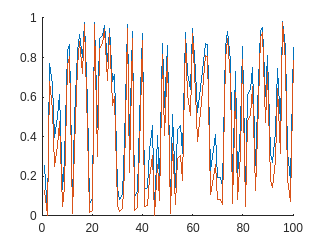

figure;hold on
plot(A(:,2));plot(B(:,2))


figure;
estimator1=estimatorIntersect(A,B);
estimator2=estimatorLowrank(A,B);
estimator3=estimatorNullNull(A,B);
% calculate error between nullnull and lowrank method
norm(estimator3-estimator2)/norm(estimator2)

ans = 0.0064

% The difference between nullnull and intersect is much larger
norm(estimator3-estimator1(:,1))/norm(estimator2)

ans = 0.0565

norm(estimator3-estimator1(:,2))/norm(estimator2)

ans = 0.0722

## Which estimator produces the most correct cone per individual?

Aorig=normpdf(wave',[450 600],[10 10]);
Aorig(:,1)=ieScale(Aorig(:,1),1);
Aorig(:,2)=ieScale(Aorig(:,2),1);
Borig=normpdf(wave',[500 600],[10 10]); % Introduce small error
Borig(:,1)=ieScale(Borig(:,1),1);
Borig(:,2)=ieScale(Borig(:,2),1);
Ca=rand(2);Cb=rand(2);
A=Aorig*Ca;
B=Borig*Cb;



estimator1=estimatorIntersect(A,B);

x2 =    -0.6286
    0.7777
   -0.2003
    0.9797


estimator2=estimatorLowrank(A,B);
estimator2flip=estimatorLowrank(B,A);
estimator3=estimatorNullNull(A,B);


% Indivudal 1
for i = [1 2]
    if(i==1)
        I=Aorig;
    else
        I = Borig;
    end
    err11=norm(estimator1(:,1)-I(:,2))/norm(I(:,2))
    % The difference between nullnull and intersect is much larger
    err12=norm(estimator1(:,2)-I(:,2))/norm(I(:,2))
    err2=norm(estimator2-I(:,2))/norm(I(:,2))
    err3=norm(estimator3-I(:,2))/norm(I(:,2))
end

err11 = 5.7096e-16

err12 = 1.2688e-16

err2 = 5.9842e-16

err3 = 1.5824e-15

err11 = 5.7096e-16

err12 = 1.2688e-16

err2 = 5.9842e-16

err3 = 1.5824e-15

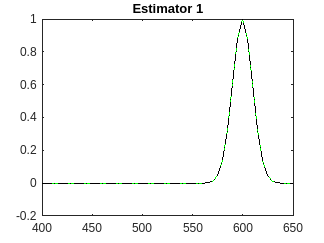

figure;
plot(wave,estimator1(:,1),'r',wave,estimator1(:,3),'g',wave,ieScale(Borig(:,2),1),'k--',wave,ieScale(Aorig(:,2),1),'k:')
title('Estimator 1')

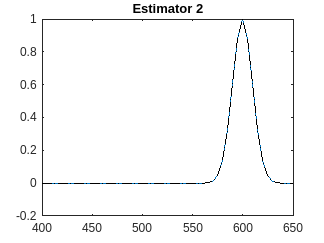

figure; 
plot(wave,estimator2,wave,ieScale(Borig(:,2),1),'k--',wave,ieScale(Aorig(:,2),1),'k:')
title('Estimator 2')

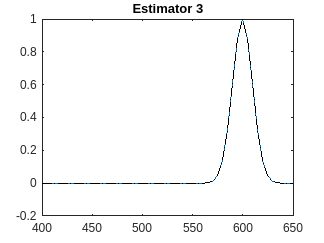

figure;
plot(wave,estimator3,wave,ieScale(Borig(:,2),1),'k--',wave,ieScale(Aorig(:,2),1),'k:')
title('Estimator 3')

## Using only 1 cone per individual

Aorig=normpdf(wave',[600],[10]);
Aorig(:,1)=ieScale(Aorig(:,1),1);

Borig=normpdf(wave',[510],[10]); % Introduce small error
Borig(:,1)=ieScale(Borig(:,1),1);
Ca=rand(1);Cb=rand(1);
A=Aorig*Ca;
B=0.2*Borig*Cb;

[U,S,V]=svds([Aorig Borig],1);;
Mlowrank = U*S*V';
estimator1=ieScale(Mlowrank,1)

estimator1 =     0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


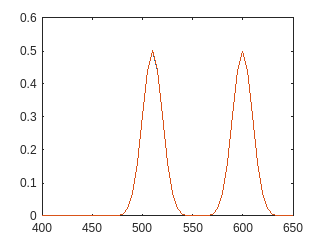

plot(wave,Mlowrank)

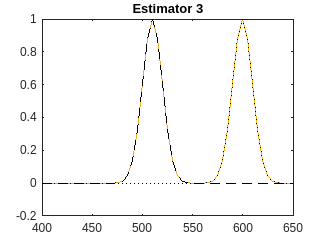



estimator3=estimatorNullNull(A,B);


figure;
plot(wave,estimator1); hold on

plot(wave,estimator3,wave,ieScale(Borig(:,1),1),'k--',wave,ieScale(Aorig(:,1),1),'k:')
title('Estimator 3')

## What if two cones are similar

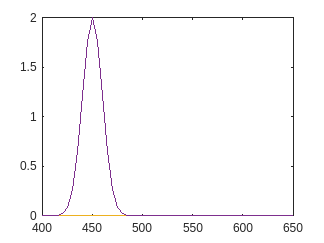

Aorig=normpdf(wave',[600 450],[10 10]);
Aorig(:,1)=ieScale(Aorig(:,1),1);
Aorig(:,2)=ieScale(Aorig(:,2),1);
Borig=normpdf(wave',[600 450],[10 10]); % Introduce small error
Borig(:,1)=ieScale(Borig(:,1),1);
Borig(:,2)=ieScale(Borig(:,2),1);

Ca=rand(2);Cb=rand(2);
A=Aorig;
B=Borig;

[U,S,V]=svds([Aorig Borig],1);;
Mlowrank = U*S*V';
estimator1=ieScale(Mlowrank,2);



estimator3=estimatorNullNull(A,B);
[U,S,V]=svd([null(A') null(B')]');

figure;
plot(wave,estimator1); hold on

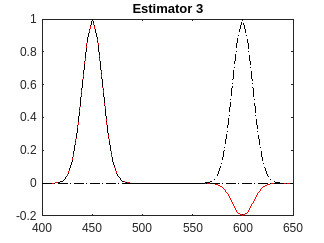

figure;
plot(wave,estimator3,'r',wave,ieScale(Borig,1),'k--',wave,ieScale(Aorig,1),'k:')
title('Estimator 3')